Project 19: Vehicle Fuel Consumption (Mechanical)

Objective: Estimate fuel usage over a driving cycle.

Core Tasks:

`•` Model vehicle speed over a simplified driving cycle.

`•` Relate fuel consumption rate to speed or acceleration.

`•` Compute total fuel consumed over the cycle.

Key Deliverables:

`•` MATLAB script computing fuel consumption.

`•` Speed vs. time and fuel usage plots.

`•` Interpretation of driving behavior on fuel efficiency.

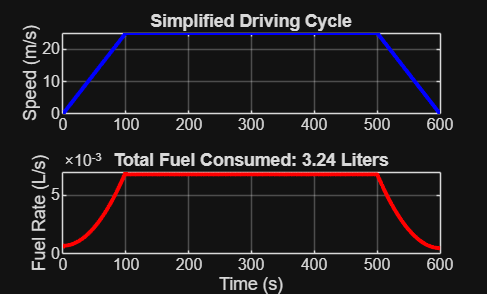

%% 1. Define Driving Cycle and Vehicle Parameters
t = 0:1:600; % 10-minute drive (600 seconds)

% Create a simplified speed profile (m/s)
% Accelerate to 25 m/s, cruise, then stop
v = zeros(size(t));
v(t <= 100) = 0.25 * t(t <= 100);          % Constant acceleration
v(t > 100 & t <= 500) = 25;                % Constant cruise (approx 55 mph)
v(t > 500) = 25 - 0.25 * (t(t > 500)-500); % Constant deceleration

%% 2. Relate Fuel Consumption to Speed and Acceleration
% Basic model: Fuel Rate (L/s) = Idle_Base + Drag_Factor*v^2 + Accel_Factor*a
% Calculating acceleration (a = dv/dt)
a = [0, diff(v)]; 

base_rate = 0.0005;  % Fuel used at idle (L/s)
drag_coeff = 0.00001; % Fuel to overcome air resistance
accel_coeff = 0.0008; % Fuel used for acceleration

% Calculate fuel rate (L/s)
% We use max(0, a) because braking usually doesn't consume extra fuel
fuel_rate = base_rate + (drag_coeff * v.^2) + (accel_coeff * max(0, a));

%% 3. Compute Total Fuel Consumed
% Total Fuel is the integral (sum) of the fuel rate over time
total_fuel = sum(fuel_rate); % Total Liters

%% 4. Visualization
figure;

% Subplot 1: Speed Profile
subplot(2,1,1);
plot(t, v, 'b', 'LineWidth', 2);
grid on;
ylabel('Speed (m/s)');
title('Simplified Driving Cycle');

% Subplot 2: Fuel Consumption Rate
subplot(2,1,2);
plot(t, fuel_rate, 'r', 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Fuel Rate (L/s)');
title(['Total Fuel Consumed: ', num2str(round(total_fuel, 2)), ' Liters']);